clear
file_in = "Data_Log_trzy_obroty.csv";
file_out = "calibrated_magn_trzy_obroty.csv";

raw_data = readtable(file_in, "VariableNamingRule","preserve");

% skalowanie
data = table();
data.time = [raw_data.("time[us]")] / 1000;

data.accX = [raw_data.("accX[mg]")] / 1000;
data.accY = [raw_data.("accY[mg]")] / 1000;
data.accZ = [raw_data.("accZ[mg]")] / 1000;

data.gyroX = [raw_data.("gyroX[mdps]")] / 1000;
data.gyroY = [raw_data.("gyroY[mdps]")] / 1000;
data.gyroZ = [raw_data.("gyroZ[mdps]")] / 1000;

data.magX = [raw_data.("magnX[mG]")] / 10;
data.magY = [raw_data.("magnY[mG]")] / 10;
data.magZ = [raw_data.("magnZ[mG]")] / 10;

data

data = 575×10 table
     time      accX      accY     accZ     gyroX     gyroY    gyroZ     magX    magY    magZ 
    ______    ______    ______    _____    ______    _____    ______    ____    ____    _____

    8267.5     0.022    -0.025     1.02     0.783    -0.14     0.345    -1.5    23.4    -28.8
    8313.2     0.022    -0.025     1.02     0.783    -0.14     0.345      -1    23.2    -28.8
    8346.3     0.024    -0.017    1.024     0.748    0.354     0.708      -1    23.2    -28.8
    8412.5     0.024    -0.017    1.024     0.748    0.354     0.708    -1.3    23.2    -28.9
      8425      0.02    -0.014    1.014     0.249    0.721     0.402    -1.

B_mierz = [data.("magX"), data.("magY"), data.("magZ")]'

B_mierz =    -1.5000   -1.0000   -1.0000   -1.3000   -1.3000   -1.3000   -1.5000   -1.5000   -1.9000   -1.9000   -1.9000   -1.9000   -2.5000   -2.5000   -2.5000   -2.7000   -2.7000   -3.0000   -3.0000   -4.8000   -4.8000   -4.0000   -4.0000   -4.0000   -4.8000   -4.8000   -6.0000   -6.0000   -7.2000   -7.2000   -9.0000   -9.0000  -11.2000  -11.2000  -13.2000  -13.2000  -16.6000  -16.6000  -16.6000  -19.0000  -19.0000  -21.1000  -21.1000  -21.1000  -25.3000  -25.3000  -27.7000  -27.7000  -30.1000  -30.1000
   23.4000   23.2000   23.2000   23.2000   23.2000   23.2000   23.5000   23.5000   22.8000   22.8000   22.8000   22.8000   23.4000   23.4000   23.4000   23.4000   23.4000   22.6000   22.6000   22.8000   22.8000   22.6000   22.6000   22.6000   23.8000   23.8000   22.8000   22.8000   22.2000   22.2000   23.7000   23.7000   24.0000   24.0000   24.3000   24.3000   23.4000   23.4000   23.4000   23.1000   23.1000   23.2000   23.2000   23.2000   24.0000   24.0000   24.6000   24.6000   25.500

%% Opcje algorytmu
B_ref = 47.31551;        % wartość referencyjna wektora pola magnetycznego w Krakowie [µT]
n = size(B_mierz,2);        % sprawdźmy długość wektora mierzonego

Ts = 0.005;

%% Wypisz podstawowe informacje o danych
fprintf('\nCzęstotliwość próbkowania:\t%2.1f [Hz]\n',1/Ts);


Częstotliwość próbkowania:	200.0 [Hz]


fprintf('Liczba próbek: \t\t\t%d\n',n);

Liczba próbek: 			575


fprintf('Czas eksperymentu:\t\t%2.1f [min]\n',n*Ts/60);

Czas eksperymentu:		0.0 [min]



%% Wybierzmy warunek początkowy optymalizacji
C0 = eye(3);                                  % początkowa macierz C
b0 = mean(B_mierz,2);                                % początkowy offset b
x0 = [C0(1,1);C0(2,2);C0(3,3);0;0;0;b0];        % wektor wartości początkowych

%% Dopasujmy optymalizacyjnie bias i macierz skośną
f = @(x)dopasujSfere(x, B_mierz, B_ref);                   % wskaźnik do funkcji celu
options = optimset('TolX', 1e-10, 'MaxFunEvals', 300);  % opcje optymalizacji
[x,fval,exitflag,output] = fminsearch(f,x0,options);    % uruchamiamy algorytm optymalizacji z funkcją celu fitSphere()

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 25.806177 




%% Odzyskaj zoptymalizowaną macierz kalibracyjną i wektor offsetu
% Po optymalizacji otrzymujemy wektor x zawierający prametry znalezionej
% macierzy i wektora kalibracyjnego. Musimy go teraz rozkodować by uzyskać
% ten wektor i macierz
[C, b] = dekodParam(x);

%% Rozkoduj macierz kalibracyjną na wzmocnienia i kąty pomiędzy osiami
Q=C'*C;
k = sqrt(diag(Q));
% Macierz K będzie diagonalna i będzie oznaczać skalę dla każdej z osi
K = diag(k);
% Macierz T będzie w tym przypadku opisywać nieprostopadłość osi, przy czym
% oś Z została wybrana jako ta nieodchylona (którąś musimy wybrać)
T = inv(C*K);           
alpha(1) = 180/pi*acos(T(1,2)*T(2,2) + T(1,3)*T(2,3));
alpha(2) = 180/pi*acos(T(2,3));
alpha(3) = 180/pi*acos(T(1,3));
fprintf('Macierz kalibracji A:\t\t%s\n',mat2str(C));

Macierz kalibracji A:		[0.855203706199466 0.00115561393749423 -0.00311298587908703;0 0.831143362459187 0.00181687848416779;0 0 1.27921864444923]


fprintf('Wektor kalibracji b:\t\t%s\n',mat2str(b));

Wektor kalibracji b:		[-20.3838720691922;28.8428473996637;24.1295413873074]


fprintf('Wzmocnienie osi X:\t\t%1.2f\n',k(1));

Wzmocnienie osi X:		0.86


fprintf('Wzmocnienie osi Y:\t\t%1.2f\n',k(2));

Wzmocnienie osi Y:		0.83


fprintf('Wzmocnienie osi Z:\t\t%1.2f\n',k(3));

Wzmocnienie osi Z:		1.28


fprintf('Kąt pomiędzy osią X i Y:\t%3.2f°\n',alpha(1));

Kąt pomiędzy osią X i Y:	90.16°


fprintf('Kąt pomiędzy osią Y i Z:\t%3.2f°\n',alpha(2));

Kąt pomiędzy osią Y i Z:	90.12°


fprintf('Kąt pomiędzy osią X i Z:\t%3.2f°\n',alpha(3));

Kąt pomiędzy osią X i Z:	89.81°


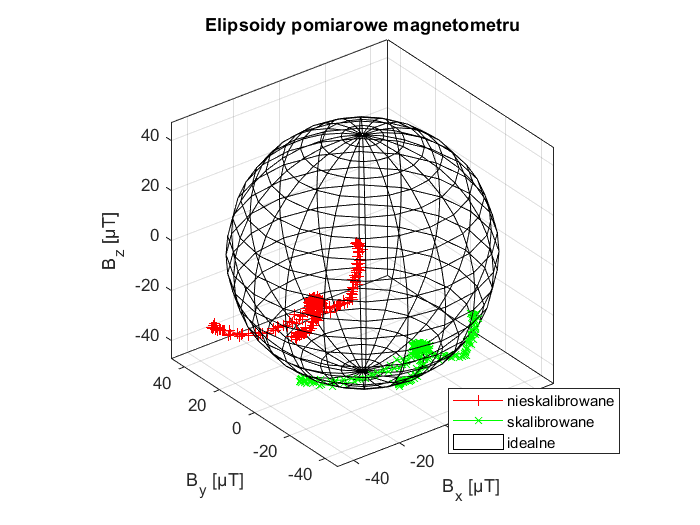


%% Skalibruj pomiar
[B_kal] = kalPomiar(B_mierz, C, b);     % Używamy znalezionych macierzy C i wekotra b do skalibrowania pomiaru

%% Oblicz wartości bezwzględne pomiaru i surowych danych
B_mag = sqrt(sum(B_mierz.^2));                                  % obliczmy wartość bezwzględną surowych pomiarów
B_mag_kal = sqrt(B_kal(1,:).^2+B_kal(2,:).^2+B_kal(3,:).^2);    % obliczmy wartość bezwzględną skalibrowanych pomiarów

%% Kilka obliczeń potrzebnych do testu poprawności rozwiazania
[C_test, b_test] = dekodParam([1; 2; 3; 4; 5; 6; 7; 8; 9]);
B_test = kalPomiar([1,2;3,4;5,6], [1 .1 .1; 0 1.1 0.2; 0 0 1.2], [1;2;3]);

%% Narysujmy sferę pomiarową
figure(), plot3(B_mierz(1,:),B_mierz(2,:),B_mierz(3,:),'+-r');
hold on, grid on;
axis('equal'), box('on');
xlabel('B_x [µT]'), ylabel('B_y [µT]'), zlabel('B_z [µT]');
title('Elipsoidy pomiarowe magnetometru');
plot3(B_kal(1,:), B_kal(2,:), B_kal(3,:), 'x-g');
[xs,ys,zs] = sphere;
sh = surf(B_ref*xs,B_ref*ys,B_ref*zs);
set(sh,'FaceColor',[0 0.1 0],'FaceAlpha',0);
legend('nieskalibrowane', 'skalibrowane', 'idealne', 'Location', 'southeast');

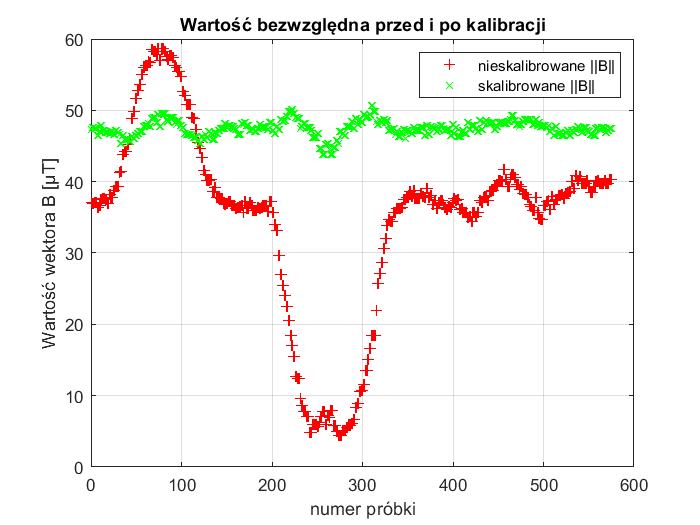


%% Narysujmy wartości bezwzględne skalibrowanego i nieskalibrowanego pomiaru
figure(), plot(B_mag,'r+');
hold on, grid on;
title('Wartość bezwzględna przed i po kalibracji');
xlabel('numer próbki'), ylabel('Wartość wektora B [µT]');
plot(B_mag_kal,'gx');
legend('nieskalibrowane ||B||', 'skalibrowane ||B||');

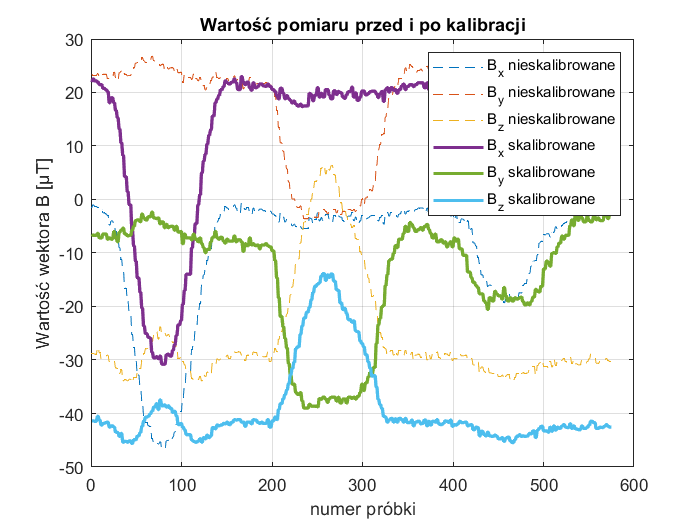


%% Narysujmy wartości skalibrowanego i nieskalibrowanego pomiaru
figure(), plot(B_mierz','--');
hold on, grid on;
title('Wartość pomiaru przed i po kalibracji');
xlabel('numer próbki'), ylabel('Wartość wektora B [µT]');
plot(B_kal(:,:)','linewidth',2);
legend('B_x nieskalibrowane', 'B_y nieskalibrowane', 'B_z nieskalibrowane', ...
       'B_x skalibrowane', 'B_y skalibrowane', 'B_z skalibrowane');


% zapisywanie do pliku
B_kal

B_kal =    21.9393   22.5242   22.5242   22.1732   22.1732   22.1732   21.9422   21.9422   21.4731   21.4731   21.4697   21.4697   20.7682   20.7682   20.7682   20.5349   20.5349   20.1857   20.1857   18.0772   18.0772   19.0139   19.0139   19.0139   18.0756   18.0756   16.6706   16.6706   15.2682   15.2682   13.1584   13.1584   10.5874   10.5874    8.2423    8.2423    4.2687    4.2687    4.2687    1.4623    1.4623   -0.9926   -0.9926   -0.9926   -5.9067   -5.9067   -8.7115   -8.7115  -11.5193  -11.5193
   -6.4582   -6.6988   -6.6988   -6.6986   -6.6986   -6.6986   -6.3397   -6.3397   -7.1804   -7.1804   -7.1784   -7.1784   -6.4572   -6.4572   -6.4572   -6.4575   -6.4575   -7.4202   -7.4202   -7.1775   -7.1775   -7.4187   -7.4187   -7.4187   -5.9743   -5.9743   -7.1755   -7.1755   -7.8972   -7.8972   -6.0909   -6.0909   -5.7312   -5.7312   -5.3666   -5.3666   -6.4498   -6.4498   -6.4498   -6.8104   -6.8104   -6.6906   -6.6906   -6.6906   -5.7271   -5.7271   -5.0067   -5.0067   -3.9238 

T = array2table(B_kal');
T.Properties.VariableNames = {'magX', 'magY', 'magZ'};
data.magX = T.magX;
data.magY = T.magY;
data.magZ = T.magZ;
writetable(data, file_out)

function [f] = dopasujSfere(x, B_mierz, B_ref)
    [C,b] = dekodParam(x);
    B_kal = kalPomiar(B_mierz, C, b);
    B_mag_kal = sqrt(sum(B_kal.^2));
    f = norm(B_mag_kal - B_ref);                              % Tutaj wpisz swój kod
end

%% Funkcja dekodująca wektor parametrów optymalizowanych x do macierzy C i wekotra b
function [C, b] = dekodParam(x)
    C = [x(1) x(4) x(6); 0 x(2) x(5); 0 0 x(3)];                         % Tutaj wpisz swój kod
    b = x(7:9);
end

%% Funkcja kalibrująca pomiar
function [B_kal] = kalPomiar(B_mierz, C, b)
    B_kal = inv(C) *(B_mierz - b);         % Tutaj wpisz swój kod
end